# RC Circuits Lab

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

## **Part 1. Construct and simulate an RC circuit**

In this part of the lab, you will construct an RC circuit in Simscape.

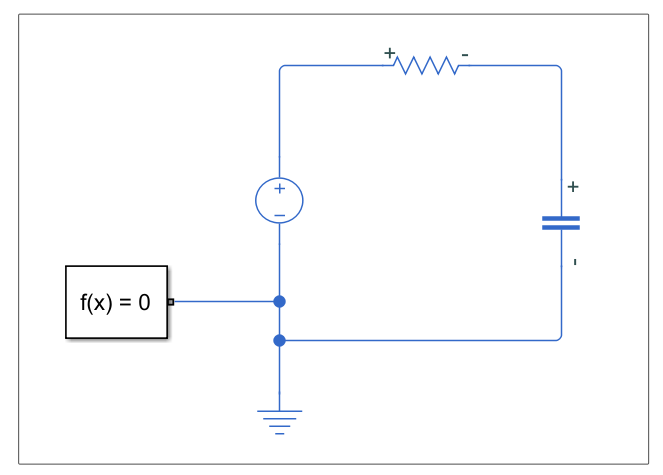

Follow the instructions below to complete the circuit. 

**Task 1. **Create a new Simulink model. 

- Get started by clicking the **Simulink** icon in the **Home **tab of the MATLAB Toolstrip. 

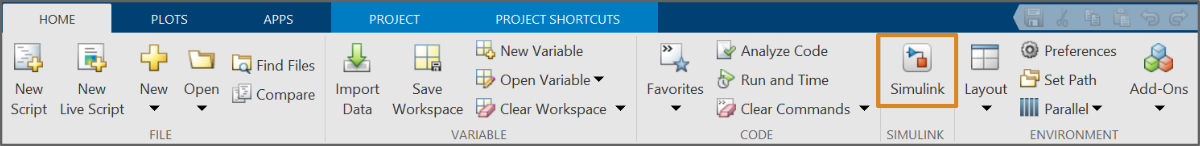

- When the Simulink Start Page appears, click the **Blank Model **icon to create a new Simulink model.

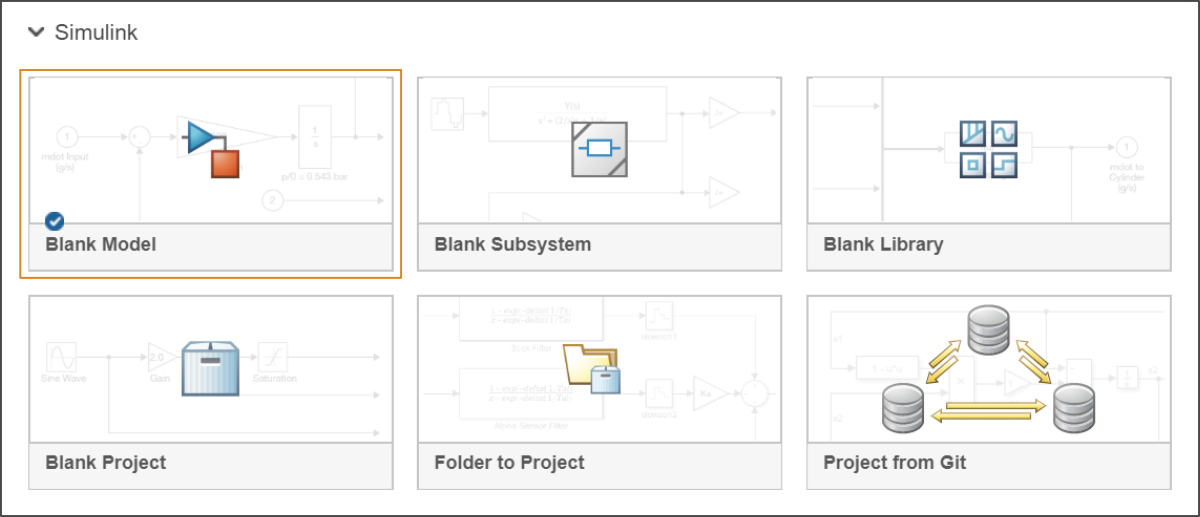

**Task 2. **There are two ways you can add blocks to the model: you can use the Library Browser or double-click the canvas. Try double-clicking on the canvas and typing "resistor" to search for blocks with "resistor" in their name. Be careful when selecting elements. The display order of the list changes based on your use, so your list order may not match the example image. You are looking for the resistor in the **Foundation Library/Electrical/Electrical Elements**. Select it from the list to add it to the canvas. 

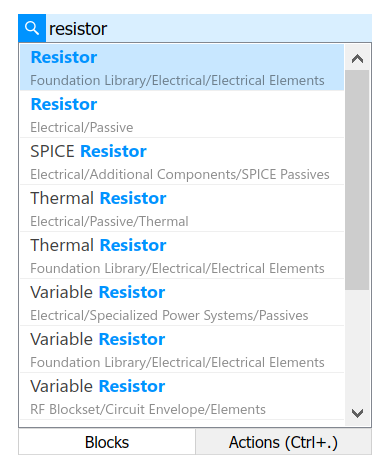

**Task 3. **The simplest resistor is the one from the **Foundation Library/Electrical/Electrical Elements**. Select it from the list to add it to the canvas. 

**Task 4. **Now add a **Capacitor **from the Foundation Library. 

**Task 5. **Rotate the capacitor using Ctrl+r. Then, connect the resistor and capacitor in series. At this point, your model should look like this:

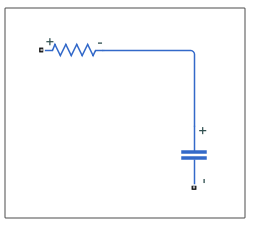

*Model after Task 5.*

 **Pro-tip**: You can zoom in and out of the Simulink canvas using the scroll wheel on your mouse or Ctrl + Plus (+).

**Task 6. **Add a **DC Voltage Source **from the **Foundation Library** to the circuit. Be careful when selecting it, as it's not necessarily the first item that appears on the search results list.

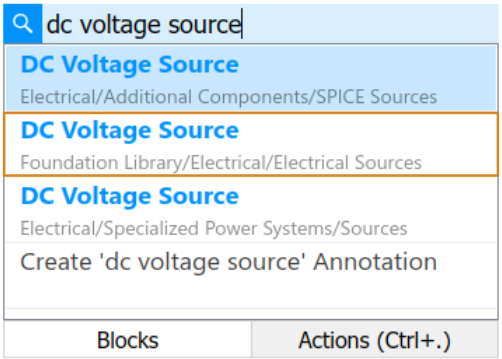

**Task 7. **Connect all three elements in series to create a charging circuit.

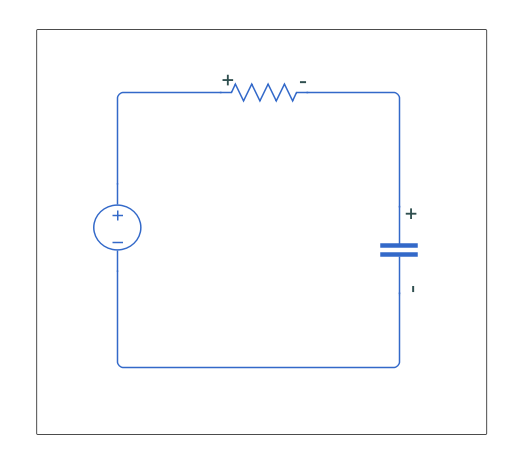

*Model after Task 7.*

**Task 8. **Try running the model. Uh-oh, looks like there's a problem. Look at the error message in the Diagnostic Viewer. You should see an error that reads:

`Each physical network must be connected to exactly one Solver Configuration block. There is no Solver Configuration block connected to Physical Network [...]`

**Task 9. **Add a **Solver Configuration block** to the model. As the error message indicated, this block is necessary for the model to run. Connect it to the circuit. The connection point does not matter, as this block only provides settings for the numerical solver. It does not change the electrical circuit.

**Task 10. ** Try rerunning the model. Looks like there's still an issue. Read the error in the Diagnostic Viewer. You should notice this helpful hint:

`[...] for example by connecting an appropriate domain reference block.`

**Task 11. **The model will not solve without an Electrical Reference block, which lets the solver know where to set the reference voltage. Add an **Electrical Reference** block from the **Foundation Library** and connect it to the negative terminal of the voltage source.

*Completed model*

**Task 12. **With the model complete, run the simulation. That's it! You have successfully simulated the RC circuit. Save your model by clicking **Save **in the **Simulation** tab.

## **Part 2. Measure a simulated RC circuit**

While the circuit was indeed simulated in the previous section, it was not very interesting to look at. In this section, you will measure the capacitor voltage and create a plot of the result.

**Task 1. **You can measure voltages in the circuit using a **Voltage Sensor **block from the **Foundation Library**. Add one to the model canvas and connect its leads (labeled + and -) to either side of the capacitor.

**Task 2. **To plot the result from the Voltage Sensor, add a **Scope **block from the **Simulink/Sinks** library.

**Task 3. **Try connecting the output of the Voltage Sensor block (labeled with an arrow) to the Scope. You should notice that they will not connect. This happens because Simscape and Simulink blocks cannot be connected to each other directly.

**Task 4. **Add a **PS-Simulink Converter** block to the model. This block converts the Simscape output into a Simulink signal. Connect the PS-Simulink Converter as shown in the diagram below.

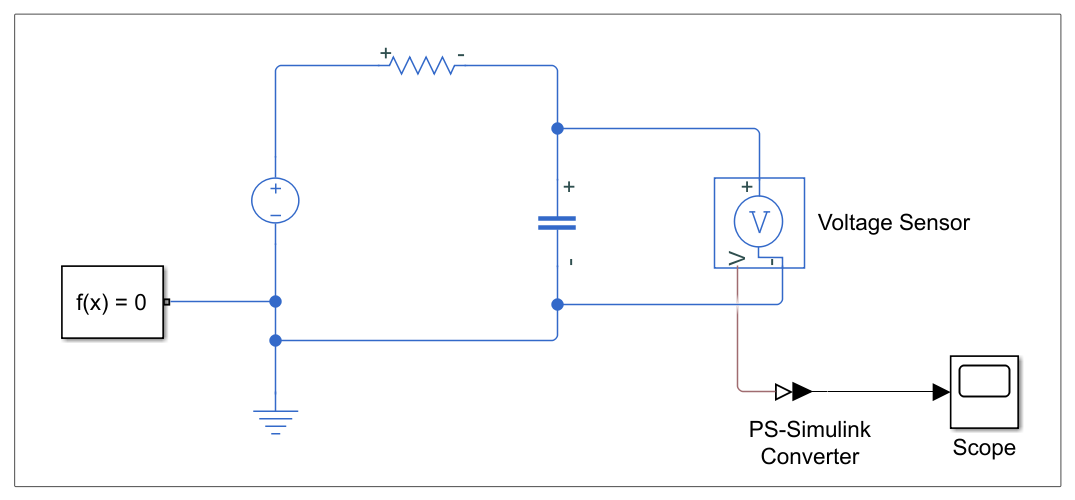

*Completed model with voltage measurements*

**Task 5. **With the measurement blocks added, run the model. Then, double-click the Scope to view the plot of the voltage. You should see this graph:

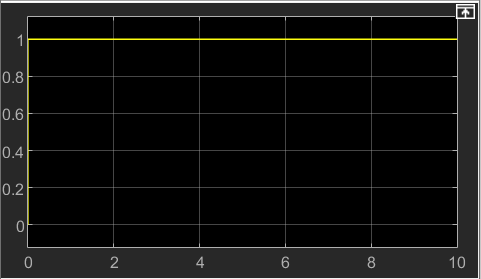

**Task 6. **This graph isn't very interesting because the default simulation time of 10 seconds is far longer than the time required for this RC circuit to charge. Change the** Stop Time** to 1e-5 seconds and rerun the model.

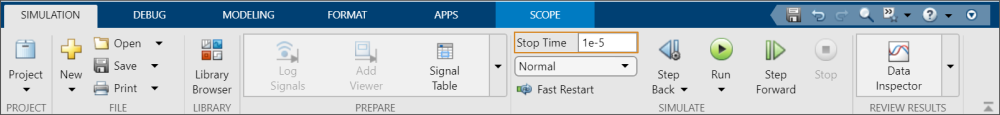

**Task 7. **Reopen the Scope. The plot should look more reasonable.

**Task 8. **Open the **Cursor Measurements **by selecting **Tools > Measurements > Cursor Measurements **in the Scope toolstrip.

**Task 9. **Use the cursors to measure the time constant of the circuit, $\tau$. For instructions on how to measure the time constant, review the last part of [RCCircuits.mlx](matlab: edit RCCircuits). Record your answer below in $\mu \text{s}$.

tau = 1.01; % In microseconds

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)